## Load DataTable00

DataTable00 = getDataTable00('G1');
rois.f1 = {...
    'HippA';
    'HippP';
    'Ent';
    'MPFC';
    };
rois.f2 = {...
    'VentralVis';
    };

## Mdl00a

formula00a = 'zTemplate ~ hemisphere + colocation + cpNonc + (1|subjectId)';
GLMM00a.f1 = fitRoiLmes(rois.f1,formula00a,DataTable00);
disp(GLMM00a.f1.FFX.tests);

                     (Intercept)                         cpNonc                         hemisphere                       colocation         
             ____________________________    ______________________________    _____________________________    ____________________________

    HippA    "t(120) = 1.02, p = 0.311;"     "t(120) = 0.854, p = 0.395;"      "t(120) = 0.269, p = 0.788;"     "t(120) = 0.35, p = 0.727;" 
    HippP    "t(120) = 1.89, p = 0.0609;"    "t(120) = 1.06, p = 0.293;"       "t(120) = 0.103, p = 0.918;"     "t(120) = 2.04, p = 0.0439;"
    Ent      "t(120) = 0.918, p = 0.36;"     "t(120) = -0.0495, p = 0.961;"    "t(120) = 0.0472, p = 0.962;"    "t(120) = 1.84, p = 0.0676;"
    MPFC     "t(120) = 0.732, p = 0.466;"    "t(120) = 0.864, p = 0.389;"      "t(120) = -

GLMM00a.f2 = fitRoiLmes(rois.f2,formula00a,DataTable00);
disp(GLMM00a.f2.FFX.tests);

                          (Intercept)                       cpNonc                        hemisphere                       colocation         
                  ___________________________    ____________________________    _____________________________    ____________________________

    VentralVis    "t(120) = 0.088, p = 0.93;"    "t(120) = 0.937, p = 0.351;"    "t(120) = -0.804, p = 0.423;"    "t(120) = 0.223, p = 0.824;"



## Mdl00b

formula00b = 'zTemplate ~ hemisphere * colocation * cpNonc + (1|subjectId)';
GLMM00b.f1 = fitRoiLmes(rois.f1,formula00b,DataTable00);
disp(GLMM00b.f1.FFX.tests);

                     (Intercept)                         cpNonc                         hemisphere                       colocation                  cpNonc:hemisphere                cpNonc:colocation              hemisphere:colocation        cpNonc:hemisphere:colocation 
             ____________________________    ______________________________    _____________________________    ____________________________    ____________________________    ______________________________    ____________________________    _____________________________

    HippA    "t(116) = 1.02, p = 0.311;"     "t(116) = 0.854, p = 0.395;"      "t(116) = 0.289, p = 0.773;"     "t(116) = 0.376, p = 0.707;"    "t(116) = -1.4, p = 0.

GLMM00b.f2 = fitRoiLmes(rois.f2,formula00b,DataTable00);
disp(GLMM00b.f2.FFX.tests);

                          (Intercept)                       cpNonc                        hemisphere                       colocation                  cpNonc:hemisphere               cpNonc:colocation             hemisphere:colocation        cpNonc:hemisphere:colocation
                  ___________________________    ____________________________    _____________________________    ____________________________    ____________________________    ____________________________    ____________________________    ____________________________

    VentralVis    "t(116) = 0.088, p = 0.93;"    "t(116) = 0.937, p = 0.351;"    "t(116) = -0.808, p = 0.421;"    "t(116) = 0.224, p = 0.823;"    "t(116) = 0.558, p = 0

## Plot: Anterior hippocampus

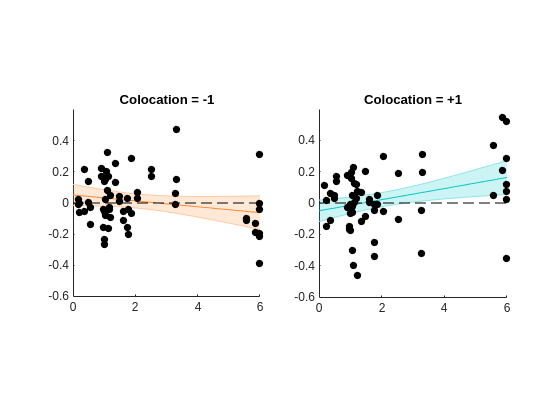

DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippA'),:);
mdl = GLMM00b.f1.mdl(...
    contains(GLMM00b.f1.mdl.Row,'HippA'),:).mdl{1};
plotZtemplateByColocationPnon(DT,mdl,[-0.6,0.6]);

## Plot: Entorhinal cortex

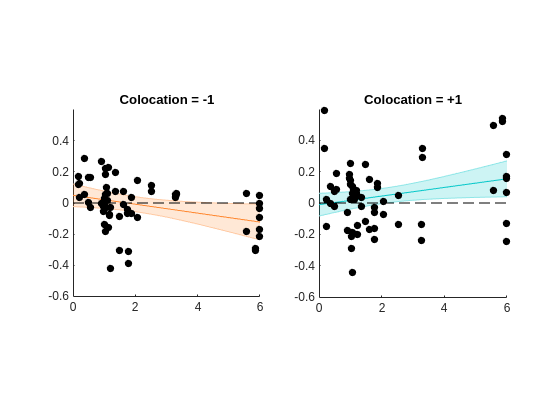

DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'Ent'),:);
mdl = GLMM00b.f1.mdl(...
    contains(GLMM00b.f1.mdl.Row,'Ent'),:).mdl{1};
plotZtemplateByColocationPnon(DT,mdl,[-0.6,0.6]);

## Plot: Ventral visual

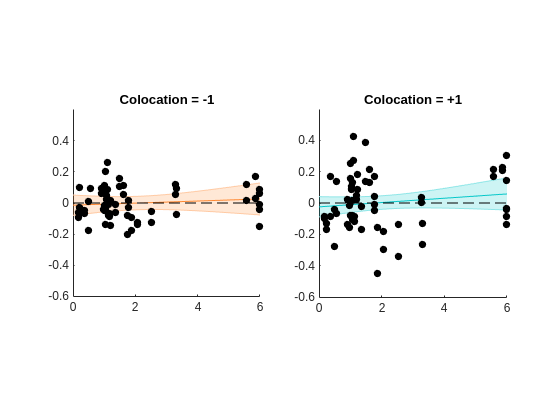

DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'VentralVis'),:);
mdl = GLMM00b.f2.mdl(...
    contains(GLMM00b.f2.mdl.Row,'VentralVis'),:).mdl{1};
plotZtemplateByColocationPnon(DT,mdl,[-0.6,0.6]);

## Plot: Posterior Hippocampus

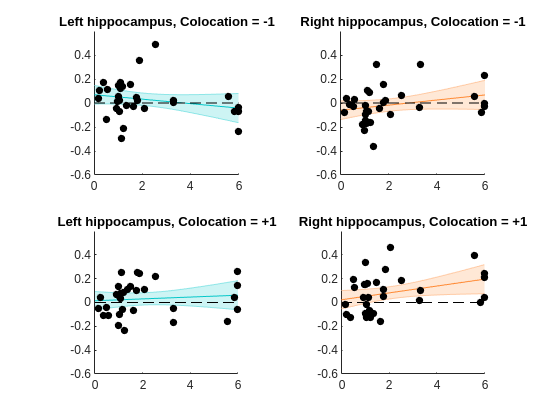

DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippP'),:);
mdl = GLMM00b.f1.mdl(...
    contains(GLMM00b.f1.mdl.Row,'HippP'),:).mdl{1};
plotZtemplateByHemiColocationPnon(DT,mdl,[-0.6,0.6]);

## MDS + Heatmaps: Anterior hippocampus, colocation=+1

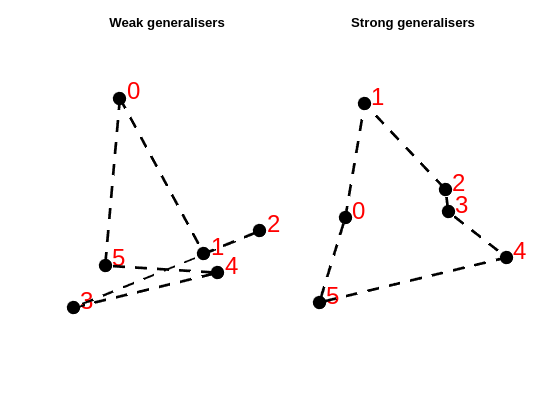

DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippA') & ...
    DataTable00.colocation==+1,:);
wd = pwd;
cd ..
subjectIds = getSubjectIds('G1');
sIds_S = getSubjectIds('G2');
cd(wd);
sIds_W = subjectIds(~ismember(subjectIds,sIds_S));
Z_S = nan(6,6,numel(sIds_S));
Z_W = nan(6,6,numel(sIds_W));
iiS = 0;
iiW = 0;
for iSubject = 1:numel(subjectIds)
    cZ = DT.patternSim(DT.subjectId==subjectIds(iSubject));
    cZ = cellfun(@(M)(M+M')/2,cZ,'UniformOutput',false);
    cZ = mean(cell2mat(reshape(cZ,1,1,2)),3);
    cZ(logical(eye(6))) = 1;
    if ismember(subjectIds(iSubject),sIds_S)
        iiS = iiS + 1;
        Z_S(:,:,iiS) = cZ;
    else
        iiW = iiW + 1;
        Z_W(:,:,iiW) = cZ;
    end
end

figure;

subplot(1,2,1);
hold on;
Z_W = mean(Z_W,3);
D = 1-Z_W;
xy = cmdscale(D,2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Weak generalisers');

subplot(1,2,2);
hold on;
Z_S = mean(Z_S,3);
D = 1-Z_S;
xy = cmdscale(D,2);
%xy = tsne(D,'Distance','correlation','NumDimensions',2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Strong generalisers');

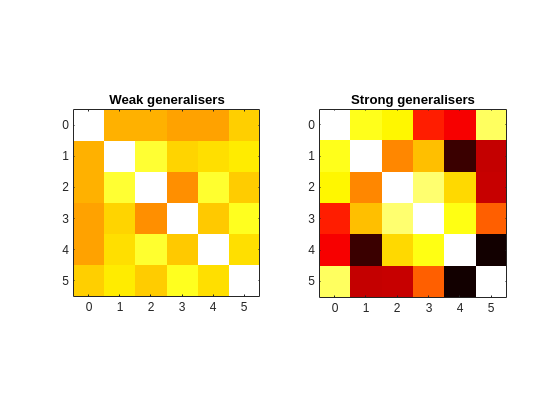

figure;
subplot(1,2,1);
h = imagesc(Z_W);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
title('Weak generalisers');
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
subplot(1,2,2);
imagesc(Z_S);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
title('Strong generalisers');

## MDS + Heatmaps: Entorhinal cortex, colocation=+1

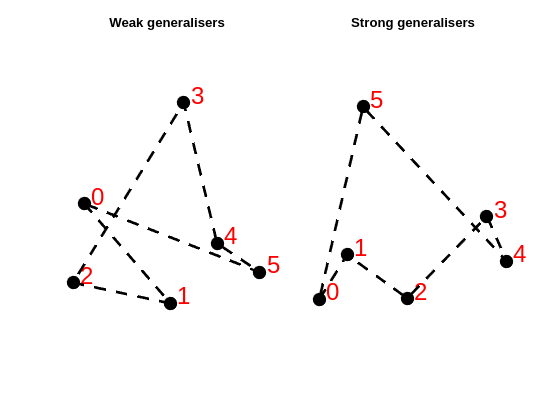

DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'Ent') & ...
    DataTable00.colocation==+1,:);
wd = pwd;
cd ..;
subjectIds = getSubjectIds('G1');
sIds_S = getSubjectIds('G2');
cd(wd);
sIds_W = subjectIds(~ismember(subjectIds,sIds_S));
Z_S = nan(6,6,numel(sIds_S));
Z_W = nan(6,6,numel(sIds_W));
iiS = 0;
iiW = 0;
for iSubject = 1:numel(subjectIds)
    cZ = DT.patternSim(DT.subjectId==subjectIds(iSubject));
    cZ = cellfun(@(M)(M+M')/2,cZ,'UniformOutput',false);
    cZ = mean(cell2mat(reshape(cZ,1,1,2)),3);
    cZ(logical(eye(6))) = 1;
    if ismember(subjectIds(iSubject),sIds_S)
        iiS = iiS + 1;
        Z_S(:,:,iiS) = cZ;
    else
        iiW = iiW + 1;
        Z_W(:,:,iiW) = cZ;
    end
end

figure;

subplot(1,2,1);
hold on;
Z_W = mean(Z_W,3);
D = 1-Z_W;
xy = cmdscale(D,2);
%xy = tsne(D,'Distance','correlation','NumDimensions',2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Weak generalisers');

subplot(1,2,2);
hold on;
Z_S = mean(Z_S,3);
D = 1-Z_S;
xy = cmdscale(D,2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Strong generalisers');

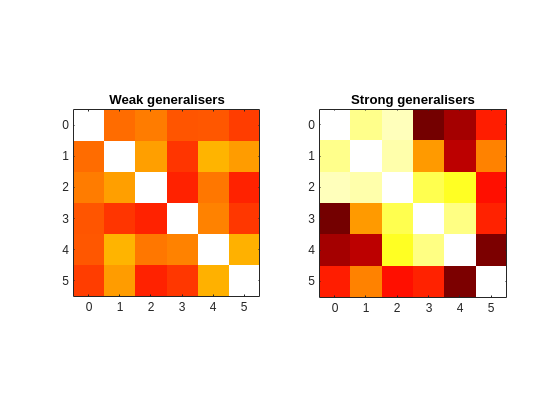

figure;
subplot(1,2,1);
h = imagesc(Z_W);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
title('Weak generalisers');
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
subplot(1,2,2);
imagesc(Z_S);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
title('Strong generalisers');

### MDS + Heatmaps: Posterior hippocampus, colocation=+1 (investigating hemisphere:pNonc interaction)

Given the subthreshold effects for posterior hippocampus for the intercept and hemisphere:pNonc interaction, as well as finding a univariate effect for pNonc in the posterior hippocampus, it is worth having a look at what the pattern sturcutre here actually looks like.

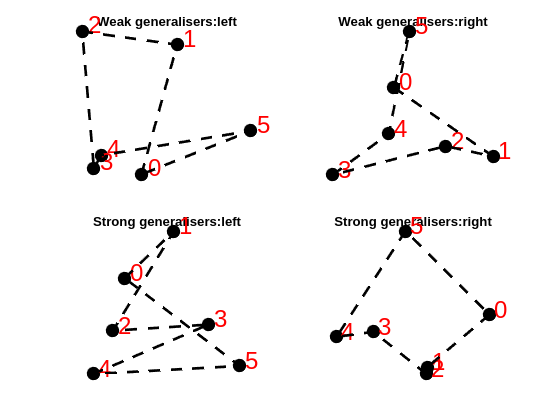

DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippP') & ...
    DataTable00.hemisphere==-1,:);
wd = pwd;
cd ..
subjectIds = getSubjectIds('G1');
sIds_S = getSubjectIds('G2');
cd(wd);
sIds_W = subjectIds(~ismember(subjectIds,sIds_S));
Z_S = nan(6,6,numel(sIds_S));
Z_W = nan(6,6,numel(sIds_W));
iiS = 0;
iiW = 0;
for iSubject = 1:numel(subjectIds)
    cZ = DT.patternSim(DT.subjectId==subjectIds(iSubject));
    cZ = cellfun(@(M)(M+M')/2,cZ,'UniformOutput',false);
    cZ = mean(cell2mat(reshape(cZ,1,1,2)),3);
    cZ(logical(eye(6))) = 1;
    if ismember(subjectIds(iSubject),sIds_S)
        iiS = iiS + 1;
        Z_S(:,:,iiS) = cZ;
    else
        iiW = iiW + 1;
        Z_W(:,:,iiW) = cZ;
    end
end

figure;

subplot(2,2,1);
hold on;
Z_W = mean(Z_W,3);
D = 1-Z_W;
xy = cmdscale(D,2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Weak generalisers:left');

subplot(2,2,3);
hold on;
Z_S = mean(Z_S,3);
D = 1-Z_S;
xy = cmdscale(D,2);
%xy = tsne(D,'Distance','correlation','NumDimensions',2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Strong generalisers:left');


DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippP') & ...
    DataTable00.hemisphere==+1,:);
wd = pwd;
cd ..
subjectIds = getSubjectIds('G1');
sIds_S = getSubjectIds('G2');
cd(wd);
sIds_W = subjectIds(~ismember(subjectIds,sIds_S));
Z_S = nan(6,6,numel(sIds_S));
Z_W = nan(6,6,numel(sIds_W));
iiS = 0;
iiW = 0;
for iSubject = 1:numel(subjectIds)
    cZ = DT.patternSim(DT.subjectId==subjectIds(iSubject));
    cZ = cellfun(@(M)(M+M')/2,cZ,'UniformOutput',false);
    cZ = mean(cell2mat(reshape(cZ,1,1,2)),3);
    cZ(logical(eye(6))) = 1;
    if ismember(subjectIds(iSubject),sIds_S)
        iiS = iiS + 1;
        Z_S(:,:,iiS) = cZ;
    else
        iiW = iiW + 1;
        Z_W(:,:,iiW) = cZ;
    end
end

subplot(2,2,2);
hold on;
Z_W = mean(Z_W,3);
D = 1-Z_W;
xy = cmdscale(D,2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Weak generalisers:right');

subplot(2,2,4);
hold on;
Z_S = mean(Z_S,3);
D = 1-Z_S;
xy = cmdscale(D,2);
%xy = tsne(D,'Distance','correlation','NumDimensions',2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Strong generalisers:right');

Looking at this, it looks like there is some subthreshold strucuture lurking in the generalisers in the right posterior hemisphere

### MDS + Heatmaps: Posterior hippocampus (investigating colocation simple effect in all subjects)

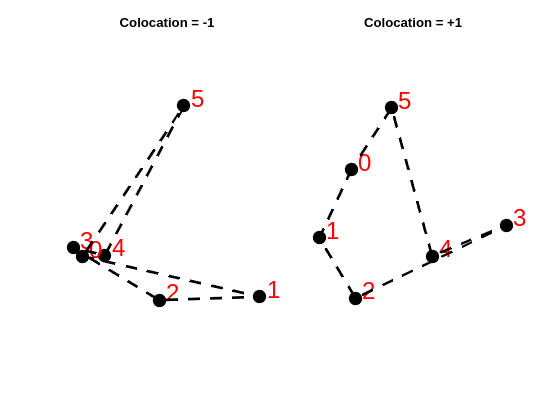

DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippP') & ...
    DataTable00.colocation==-1,:);
wd = pwd;
cd ..
if ismember(subjectIds(iSubject),sIds_S)
    iiS = iiS + 1;
    Z_S(:,:,iiS) = cZ;
else
    iiW = iiW + 1;
    Z_W(:,:,iiW) = cZ;
end
subjectIds = getSubjectIds('G1');
cd(wd);
sIds_W = subjectIds;
Z_W1 = nan(6,6,numel(sIds_W));
iiW = 0;
for iSubject = 1:numel(subjectIds)
    cZ = DT.patternSim(DT.subjectId==subjectIds(iSubject));
    cZ = cellfun(@(M)(M+M')/2,cZ,'UniformOutput',false);
    cZ = mean(cell2mat(reshape(cZ,1,1,2)),3);
    cZ(logical(eye(6))) = 1;
    iiW = iiW + 1;
    Z_W1(:,:,iiW) = cZ;
end

figure;

subplot(1,2,1);
hold on;
Z_W1 = mean(Z_W1,3);
D = 1-Z_W1;
xy = cmdscale(D,2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Colocation = -1');


DT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippP') & ...
    DataTable00.colocation==+1,:);
wd = pwd;
cd ..
subjectIds = getSubjectIds('G1');
cd(wd);
sIds_W = subjectIds;
Z_W2 = nan(6,6,numel(sIds_W));
iiW = 0;
for iSubject = 1:numel(subjectIds)
    cZ = DT.patternSim(DT.subjectId==subjectIds(iSubject));
    cZ = cellfun(@(M)(M+M')/2,cZ,'UniformOutput',false);
    cZ = mean(cell2mat(reshape(cZ,1,1,2)),3);
    cZ(logical(eye(6))) = 1;
    iiW = iiW + 1;
    Z_W2(:,:,iiW) = cZ;
end
subplot(1,2,2);
hold on;
Z_W2 = mean(Z_W2,3);
D = 1-Z_W2;
xy = cmdscale(D,2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Colocation = +1');

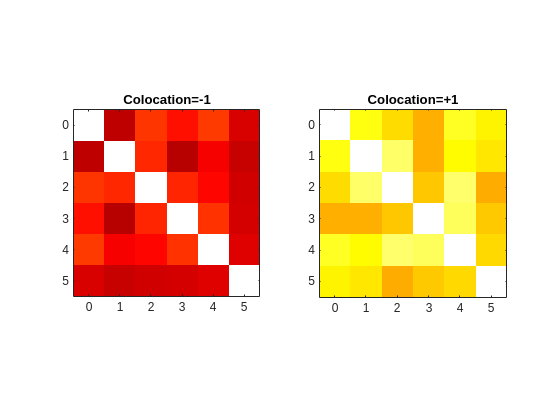

figure;
subplot(1,2,1);
h = imagesc(Z_W1);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
title('Colocation=-1');
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
subplot(1,2,2);
imagesc(Z_W2);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
title('Colocation=+1');

Looking at this, the evidence for a group-wide structure in colocation +1 in the posterior hippocampus looks more iffy (of course interaction is also speculatory)